clear all;

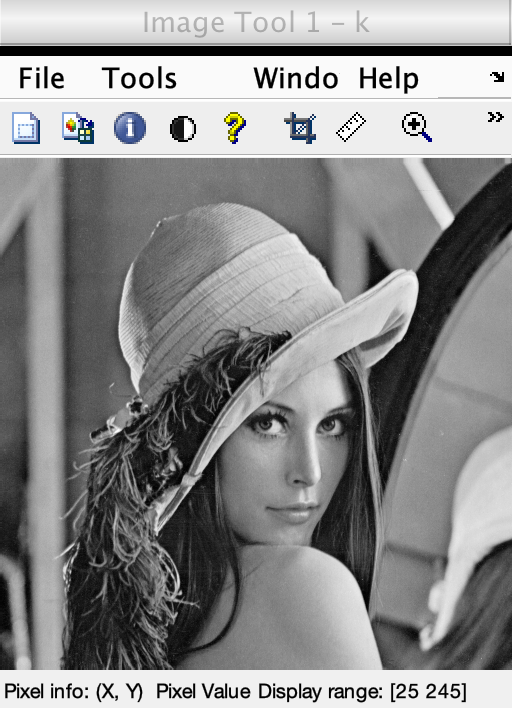

% MATLAB code for prewitt
% operator edge detection
k=imread("Lenna.png");
%k=imread("city.jpg");

k=rgb2gray(k);
k1=double(k);

p_msk=[-1 0 1; -1 0 1; -1 0 1];

kx=conv2(k1, p_msk, 'same');
ky=conv2(k1, p_msk', 'same');
ked=sqrt(kx.^2 + ky.^2);

% display the images.
imtool(k,[]);

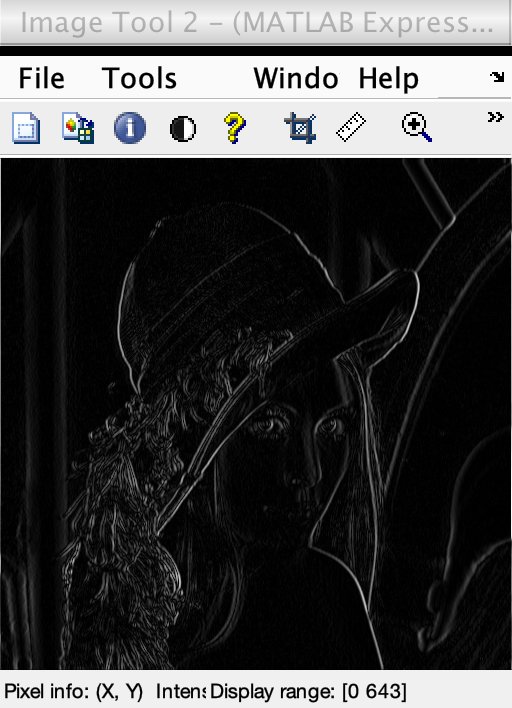


% display the edge detection along x-axis.
imtool(abs(kx), []);

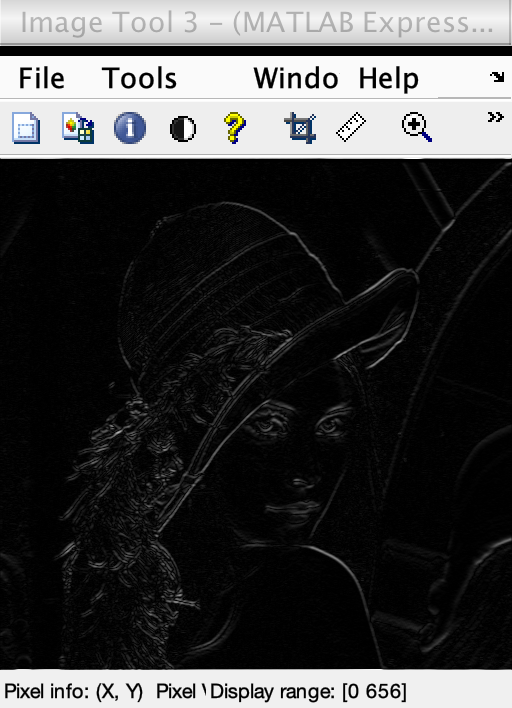


% display the edge detection along y-axis.
imtool(abs(ky),[]);

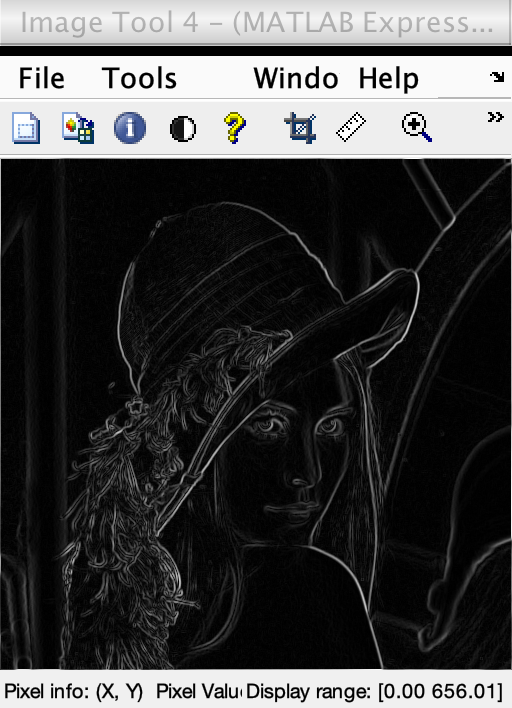


% display the full edge detection.
imtool(abs(ked),[]);